clear;clc;close all;

%sphere = [0,0,0,1];
v = [-1,1,0]/2;
%v = [0.971779788708135  -0.235889894354067 0];
d = -[1,-0.5,0];
r = 1;
[t,q] = IntersectRaySphere(v,d,[0,0,0],r)

t =    0.271779788708135


q =   -0.771779788708135   0.635889894354067                   0


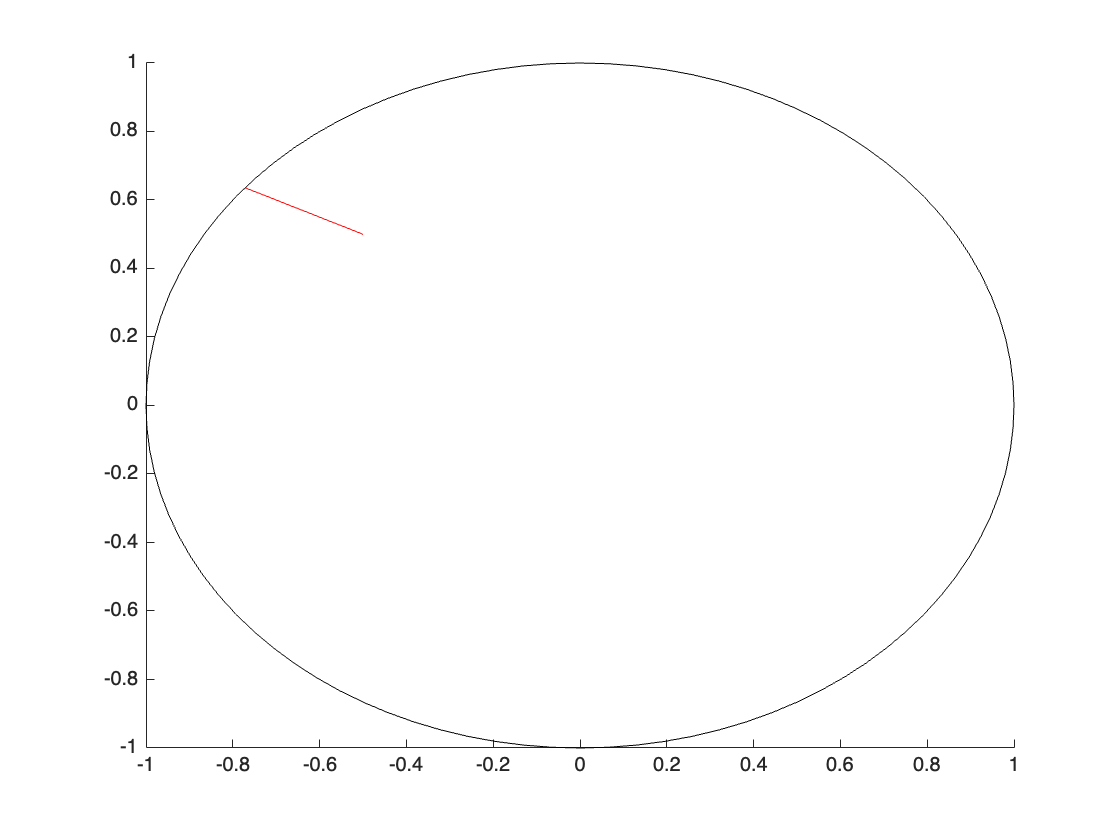

rectangle('Position',[0-r,0-r,2*r,2*r],'Curvature',[1 1])
hold on
plot([v(1),q(1)],[v(2),q(2)],'r-')

% Stage 2: Space directions
%viewDir = [1,0,0];
%viewPos = [0,1.0001,0];
viewDir = [1,-0.5,0];
viewPos = [-3,2.63,0];

planetCenter = [0,0,0];
rGround = 1; % scaled to 1
rAtmosphere = 3; % scaled to 0.011
nCollisionSpheres = 10;
rCollisionSpheres = (10.^(linspace(0,2,nCollisionSpheres).')-1)/(1e2-1);
rCollisionSpheres = rGround + (rAtmosphere-rGround)*rCollisionSpheres;
collisionSpheres = [repmat(planetCenter,[nCollisionSpheres,1]), rCollisionSpheres];

[intersections, hits_ground] = IntersectRayAtmosphere(viewPos, ...
                                    viewDir, ...
                                    collisionSpheres(:,1:3),...
                                    rCollisionSpheres) 

intersections =   -2.074417226033737   2.167208613016868                   0
  -1.286602479458986   1.773301239729493                   0
  -0.777082612939995   1.518541306469997                   0
  -0.433803857230163   1.346901928615081                   0
  -0.191651416383662   1.225825708191831                   0
  -0.012296685994719   1.136148342997360                   0
   0.128238270029434   1.065880864985283                   0
   0.248432977301272   1.005783511349364                   0
   0.384732595810772   0.937633702094614                   0
   0.519267404189228   0.870366297905386                   0


hits_ground = logical
   0


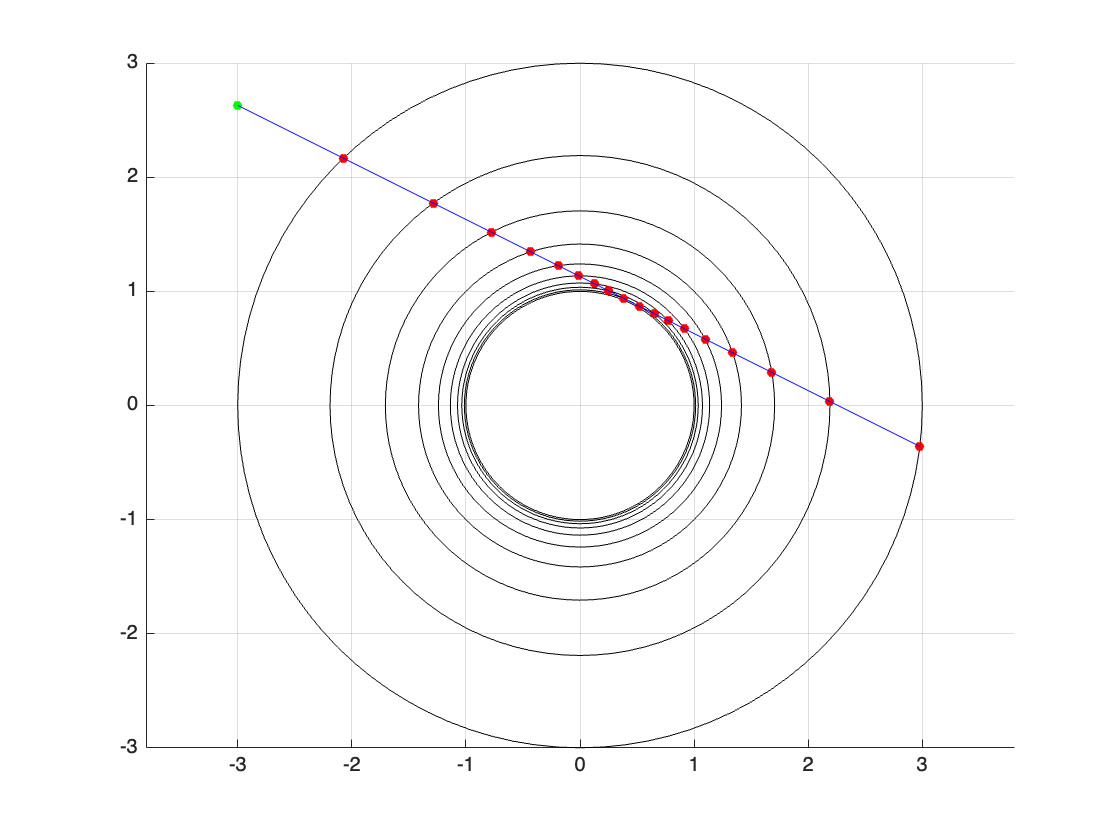


% plot spheres
clf,figure
for i = 1:nCollisionSpheres
rectangle('Position',[collisionSpheres(i,1)-rCollisionSpheres(i),...
    collisionSpheres(i,2)-rCollisionSpheres(i),...
    2*rCollisionSpheres(i),2*rCollisionSpheres(i)],'Curvature',[1 1],'EdgeColor','k'),hold on
end
scatter(intersections(:,1),intersections(:,2),24,'red','filled')
scatter(viewPos(1),viewPos(2),24,'green','filled')
plot([viewPos(1),intersections(1,1)],...a
        [viewPos(2),intersections(1,2)],'b-')
for i = 1:(size(intersections,1)-1)
    plot([intersections(1:end-1,1),intersections(2:end,1)],...
        [intersections(1:end-1,2),intersections(2:end,2)],'b-')
end
axis equal, grid on